# Thermoeconomic Input-Output Analysis

This LiveScript illustrate the application of input-output analysis to thermoeconomics

### Define the Input-Output Table of the System

tio=[0 45 30 0 0 0;...
   0 0 0 0 0 35;...
   0 0 0 30 0 0;...
   0 0 0 0 5 20;...
   0 0 4 0 0 0;...
   100 0 0 0 0 0];
fdisplay(tio,'%8.1f','Input Output Table')

Input Output Table
     0.0    45.0    30.0     0.0     0.0     0.0
     0.0     0.0     0.0     0.0     0.0    35.0
     0.0     0.0     0.0    30.0     0.0     0.0
     0.0     0.0     0.0     0.0     5.0    20.0
     0.0     0.0     4.0     0.0     0.0     0.0
   100.0     0.0     0.0     0.0     0.0     0.0



### Show the System Graph

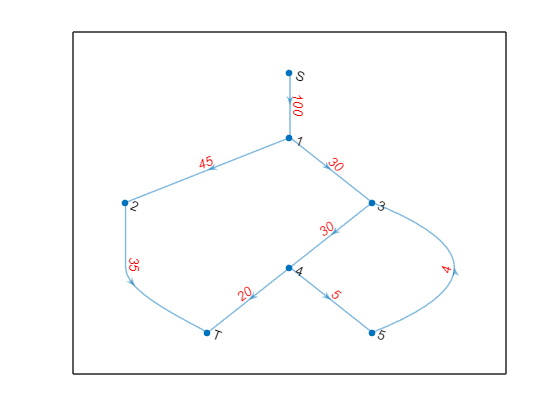

N=size(tio,1)-1;
names = ["S",string(1:N),"T"];
E=adjacencyTable(tio);
dg = digraph(E);
plot(dg,'Layout','layered','NodeLabel',names,'EdgeLabel',dg.Edges.Weight,'EdgeLabelColor','red');

#### Test if is the system is Productive

D = transitiveClosure(E);
sol = all(D(1,:)) & all(D(:,end));
fprintf('Productive graph: %s', mat2str(sol))

Productive graph: true

if ~sol,return; end

### Compute Processes Costs

#### Compute the technical coeficients matrix

N=size(E,1);
x=sum(E,2);
A = divideCol(E,x);
fdisplay(A,'%10.4f','Technical coeficient matrix')

Technical coeficient matrix
    0.0000    1.3333    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    1.2857    1.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    1.2000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    1.2500    0.0000
    0.0000    0.0000    0.0000    0.1333    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



fprintf('Spectral Ratio: %10.4f',abs(eigs(A,1)));

Spectral Ratio:     0.5848

#### Compute Leontief operator

L=eye(N)/(eye(N)-A);
fdisplay(L,'%10.4f','Leontief Operator');

Leontief Operator
    1.0000    1.3333    1.7143    1.6667    2.0000    2.5000    0.0000
    0.0000    1.0000    1.2857    1.2500    1.5000    1.8750    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    1.2500    1.5000    1.8750    0.0000
    0.0000    0.0000    0.0000    0.2083    1.2500    1.5625    0.0000
    0.0000    0.0000    0.0000    0.1667    0.2000    1.2500    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000



#### Calculate the unit cost of the processes

c0=zeros(1,N); c0(1)=1;
c=c0*L;
fdisplay(c,'%10.4f','Process Unit Cost');

Process Unit Cost
    1.0000    1.3333    1.7143    1.6667    2.0000    2.5000    0.0000



#### Compute and check process production

w0=zeros(N,1);w0(N)=sum(E(:,N));
fdisplay(xx','%10.1f','Process Production');

Process Production
     100.0      75.0      35.0      30.0      25.0       4.0       0.0



#### Calculate distribution matrix

B=divideRow(E,x);
fdisplay(full(B),'%10.4f','Distribution Matrix')

Distribution Matrix
    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.6000    0.4000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000
    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.2000    0.8000
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



#### Calculate the distribution cost operator

G=eye(N)/(eye(N)-B);
fdisplay(G,'%10.4f','Distribution Cost Operator');

Distribution Cost Operator
    1.0000    1.0000    0.6000    0.5000    0.5000    0.1000    1.0000
    0.0000    1.0000    0.6000    0.5000    0.5000    0.1000    1.0000
    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000
    0.0000    0.0000    0.0000    1.2500    1.2500    0.2500    1.0000
    0.0000    0.0000    0.0000    0.2500    1.2500    0.2500    1.0000
    0.0000    0.0000    0.0000    1.2500    1.2500    1.2500    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000



#### Calculate exergy cost

C0=zeros(1,N); C0(1)=sum(E(1,:));
fdisplay(C0*G,'%10.1f','Process Exergy cost')

Process Exergy cost
     100.0     100.0      60.0      50.0      50.0      10.0     100.0



### Show the Cost Graph

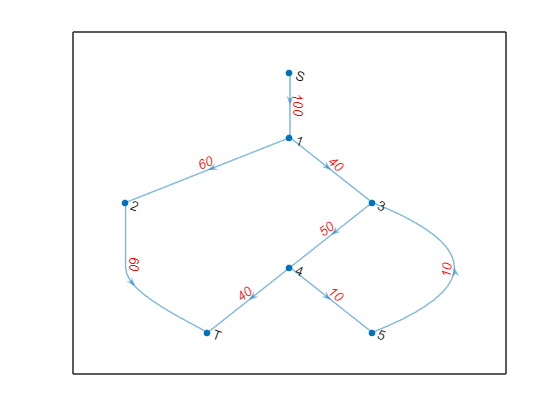

uc=[c(2:end-1),c(1)];
CostTable=scaleRow(tio,uc);
CE=adjacencyTable(CostTable);
cdg = digraph(CE);
plot(cdg,'Layout','layered','NodeLabel',names,'EdgeLabel',cdg.Edges.Weight,'EdgeLabelColor','red');

function res=adjacencyTable(table)
% Build adjacency table from Table IO
    N=size(table,1)-1; T=N+2;
    source=table(end,1:end-1);
    output=table(1:end-1,end);
    internal=table(1:end-1,1:end-1);
    res=[0 source 0;zeros(N,1) internal output;zeros(1,T)];
end